# MEDTRONIC CONFIDENTIAL

## DO NOT DISTRIBUTE

## RESEARCH USE ONLY


% To be shared only within Medtronic and with UCH researchers
% NOT VALIDATED, FOR RESEARCH USE IN MDT-UCH COLLABORATIVE STUDY A 1718256

% Caleb Zarns 5/2/2023
% Generate PSD figures from Stimulation Titration BrainSense Streams

%% CCC
close all
clear all
clc
LW = 3;
FontS = 12;

%% Import Read

fs=250;
nfft=250;
window=250;
overlap=150;
lfpsamplerate=2;
color = turbo(11);

[val] = Import_Read;

fname = 'Z:\RadcliffeE\Thesis_PD Neuro-correlated Kinematics\Data\Clinical\DLC_LFP\09_12_2023_LSTN\Report_Json_Session_Report_20230912T115956.json'

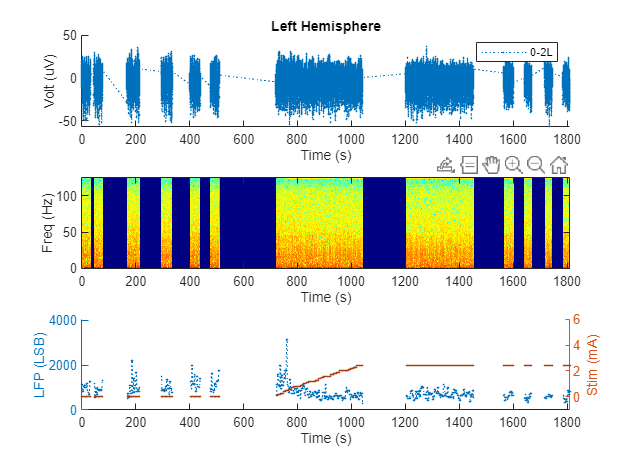

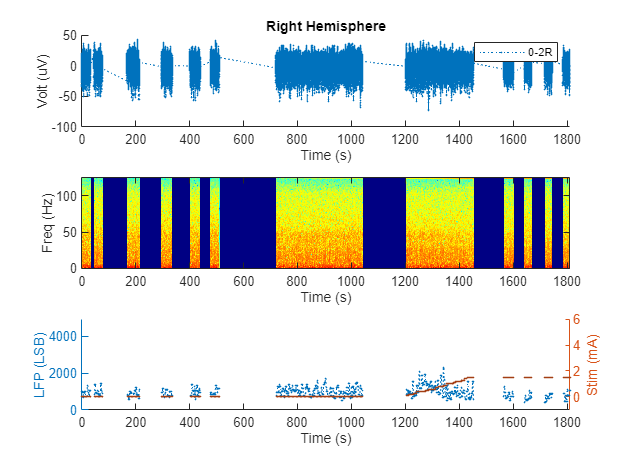


UCH_PowerSnapTD_short(val)
UCH_PowerSnapLFPCL_short(val)

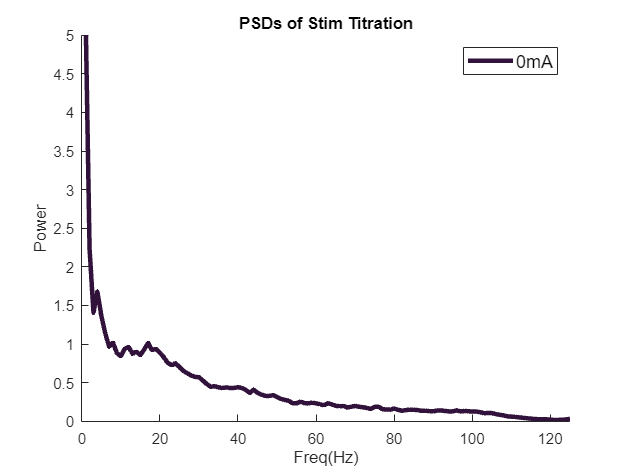

%%
% Enter stream information
i = 2; % Enter BrainSenseLfp Row of interest
k = "Left"; % STIM % Choose Left or Right Hemisphere 
k1 = "Left"; % SENSE
freqband = 10:15;
TuneFactor = 0.0035; %0.025;

% n = 7; 
% Enter BrainSenseTimeDomain Row of interest (Auto selected by section below)

% Determine time domain stream associated with lfp stream
d1 = datetime(val.BrainSenseLfp(i).FirstPacketDateTime,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSS''Z');
khemi = find(contains({val.BrainSenseTimeDomain(:).Channel},k1,'IgnoreCase',true));
counter = 1;
for n = khemi
    d2(counter) = datetime(val.BrainSenseTimeDomain(n).FirstPacketDateTime,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSS''Z');
counter = counter + 1;
end
dt = between(d1,d2);
dt = time(dt);
[dtmin,dtminI] = min(abs(dt));
n = khemi(dtminI);

data = val.BrainSenseTimeDomain(n).TimeDomainData;

%Setup categorization of stim amplitude timing
check = [];
base = [];
step05 = [];
step10 = [];
step15 = [];
step20 = [];
step25 = [];
step30 = [];
step35 = [];
step40 = [];
step45 = [];
step50 = [];
for j = 1:length(val.BrainSenseLfp(i).LfpData)
    try
        if eval(strcat('val.BrainSenseLfp(i).LfpData(j-1).',k,'.mA')) > eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA'))
            savecounter = j-1;
            break
        else savecounter = j;
        end
    catch
    end
    check = [check,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA'))];
    if eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) == 0 % Add check for TicksInMses for sync lfp and td for comparing.
        base = [base,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 0.5
        step05 = [step05,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 1
        step10 = [step10,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 1.5
        step15 = [step15,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 2
        step20 = [step20,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 2.5
        step25 = [step25,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 3
        step30 = [step30,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 3.5
        step35 = [step35,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 4
        step40 = [step40,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 4.5
        step45 = [step45,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 5
        step50 = [step50,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k1,'.LFP'))];
    end
end
c = [base,step05,step10,step15,step20,step25,step30,step35,step40,step45,step50];
if range(check) == 0 % If range is 0, plot is meaningless and skipped
    check = [];
    %     continue
end
check = [];
psdvar = [];

f4 = figure('Name',strcat(k1,'Titration PSD'));
savecounter2 = length(val.BrainSenseLfp(i).LfpData);
data = val.BrainSenseTimeDomain(n).TimeDomainData;
hold on
progress = 0;

if ~isempty(base)
    [pxx,f] = pwelch(data(1:round(length(base)/length(c)*length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','0mA','Color',color(1,:))
    progress = progress + round(length(base)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(1,:) = pxx;
end
if progress == 0
    progress = 1;
end
if ~isempty(step05)
    [pxx,f] = pwelch(data(progress : progress + round(length(step05)/length(c)*length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','0.5mA','Color',color(2,:))
    progress = progress + round(length(step05)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(2,:) = pxx;

end
if ~isempty(step10)
    [pxx,f] = pwelch(data(progress : progress + round(length(step10)/length(c)*length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','1mA','Color',color(3,:))
    progress = progress + round(length(step10)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(3,:) = pxx;
end
if ~isempty(step15)
    [pxx,f] = pwelch(data(progress : progress + round(length(step15)/length(c)*length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','1.5mA','Color',color(4,:))
    progress = progress + round(length(step15)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(4,:) = pxx;

end
if ~isempty(step20)
    [pxx,f] = pwelch(data(progress : progress + round(length(step20)/length(c)*length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','2mA','Color',color(5,:))
    progress = progress + round(length(step20)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(5,:) = pxx;
end
if ~isempty(step25)
    [pxx,f] = pwelch(data(progress : min(progress + round(length(step25)/length(c)*length(data)*(savecounter/savecounter2)),length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','2.5mA','Color',color(6,:))
    progress = progress + round(length(step25)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(6,:) = pxx;
end
if ~isempty(step30)
    [pxx,f] = pwelch(data(progress : min(progress + round(length(step30)/length(c)*length(data)*(savecounter/savecounter2)),length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','3mA','Color',color(7,:))
    progress = progress + round(length(step30)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(7,:) = pxx;

end
if ~isempty(step35)
    [pxx,f] = pwelch(data(progress : min(progress + round(length(step35)/length(c)*length(data)*(savecounter/savecounter2)),length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','3.5mA','Color',color(8,:))
    progress = progress + round(length(step35)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(8,:) = pxx;

end
if ~isempty(step40)
    [pxx,f] = pwelch(data(progress : min(progress + round(length(step40)/length(c)*length(data)*(savecounter/savecounter2)),length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','4mA','Color',color(9,:))
    progress = progress + round(length(step40)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(9,:) = pxx;

end
if ~isempty(step45)
    [pxx,f] = pwelch(data(progress : min(progress + round(length(step45)/length(c)*length(data)*(savecounter/savecounter2)),length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','4.5mA','Color',color(10,:))
    progress = progress + round(length(step45)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(10,:) = pxx;
end
if ~isempty(step50)
    [pxx,f] = pwelch(data(progress : min(progress + round(length(step50)/length(c)*length(data)*(savecounter/savecounter2)),length(data)*(savecounter/savecounter2))),window,overlap,nfft,fs);
    semilogy(f,sqrt(pxx),'LineWidth',LW,'DisplayName','5mA','Color',color(11,:))
    progress = progress + round(length(step50)/length(c)*length(data)*(savecounter/savecounter2));
    psdvar(11,:) = pxx;
end
title('PSDs of Stim Titration')
set(gcf,'color','w')
legend('FontSize',FontS)
xlim([0 125])
xlabel('Freq(Hz)')
ylabel('Power')
ylim([0 5])

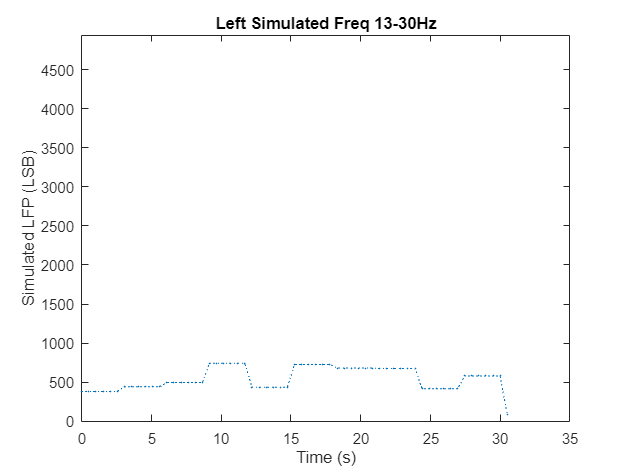


freqband = [13 30];
%%
TuneFactor = 0.0035; %0.025;


customLFP = [];
gain = val.BrainSenseTimeDomain(n).Gain;
ADC = (data*gain*(2^15.57))/1200000;


for m = 1:123:(length(data)-2*nfft)
    [pxx,f] = pwelch(ADC(m:m+250),window,overlap,nfft,fs);
    customLFP = [customLFP, 1.6951*sum(pxx(freqband(1):freqband(end)).^2)];
end
for m = 1:6:length(customLFP)-6
    customLFP(m:m+5) = mean(customLFP(m:m+5));
end
customLFP = customLFP*TuneFactor;


timexcustomLFP = linspace(0,length(customLFP)/lfpsamplerate,length(customLFP));

f52 = figure('Name',strcat(k1,'_Simulated Freq_',string(freqband(1)),'-',string(freqband(end)),'Hz'));
plot(timexcustomLFP,customLFP,'Linestyle',':','Marker','.','MarkerSize',3)
set(gcf,'color','w')
xlabel('Time (s)')
ylabel('Simulated LFP (LSB)')
ylim([-1 10*median(customLFP)]);
title(strcat(k1,' Simulated Freq',{' '},string(freqband(1)),'-',string(freqband(end)),'Hz'))


f53 = figure('Name',strcat(k1,...
    '_Simulated Freq_',...
    string(freqband(1)),...
    '-',...
    string(freqband(end)),'Hz'));
%Setup categorization of stim amplitude timing
check = [];
base = [];
step05 = [];
step10 = [];
step15 = [];
step20 = [];
step25 = [];
step30 = [];
step35 = [];
step40 = [];
step45 = [];
step50 = [];
for j = 1:length(val.BrainSenseLfp(i).LfpData)
    try
        if eval(strcat('val.BrainSenseLfp(i).LfpData(j-1).',k,'.mA')) > eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA'))
            savecounter = j-1;
            break
        else savecounter = j;
        end
    catch
    end
    check = [check,eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA'))];
    if eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) == 0 % Add check for TicksInMses for sync lfp and td for comparing.
        base = [base,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 0.5
        step05 = [step05,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 1
        step10 = [step10,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 1.5
        step15 = [step15,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 2
        step20 = [step20,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 2.5
        step25 = [step25,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 3
        step30 = [step30,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 3.5
        step35 = [step35,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 4
        step40 = [step40,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 4.5
        step45 = [step45,customLFP(j)];
    elseif eval(strcat('val.BrainSenseLfp(i).LfpData(j).',k,'.mA')) <= 5
        step50 = [step50,customLFP(j)];
    end
end

Index exceeds the number of array elements. Index must not exceed 61.

c = [base,step05,step10,step15,step20,step25,step30,step35,step40,step45,step50];
grp = [zeros(1,length(base)),0.5*ones(1,length(step05)),1*ones(1,length(step10)),...
    1.5*ones(1,length(step15)),2*ones(1,length(step20)),2.5*ones(1,length(step25)),...
    3*ones(1,length(step30)),3.5*ones(1,length(step35)),4*ones(1,length(step40)),...
    4.5*ones(1,length(step45)),5*ones(1,length(step50))];
boxchart(grp,c)
set(gcf,'color','w')
xlabel('Stimulation Level (mA)')
ylabel('LFP (a. u.)')
title(strcat(k1,' Simulated Freq',{' '},string(freqband(1)),'-',string(freqband(end)),'Hz'))


function [val,path] = Import_Read()
%Import_Read Lets user select .json file for use in the Field Support
%Dashboard
%   This function allows the user to select a .json file and decodes it
%   into a structure labeled 'val' which is then used to populate the Field
%   Support Dashboard
% [file,path] = uigetfile('*.json','Select .json file',...

[file,path] = uigetfile('*.json','Select .json file');
fname = [path,file]
val = jsondecode(fileread(fname));

end
